% AE675 Project
% Submitted by Chourishi

clear all

seed=180252;%Your roll number
rng(seed);
L= 0.75+0.5*rand(1,1);%length L
theta = 30 + 30*rand(1,1);%Angle theta
TA = 500+200*rand(1,1);%Temperature at point A


A = 6e-4;
K = 1;% Waste
E = 210e9;
alpha = 1e-6;

% alpha = 0;


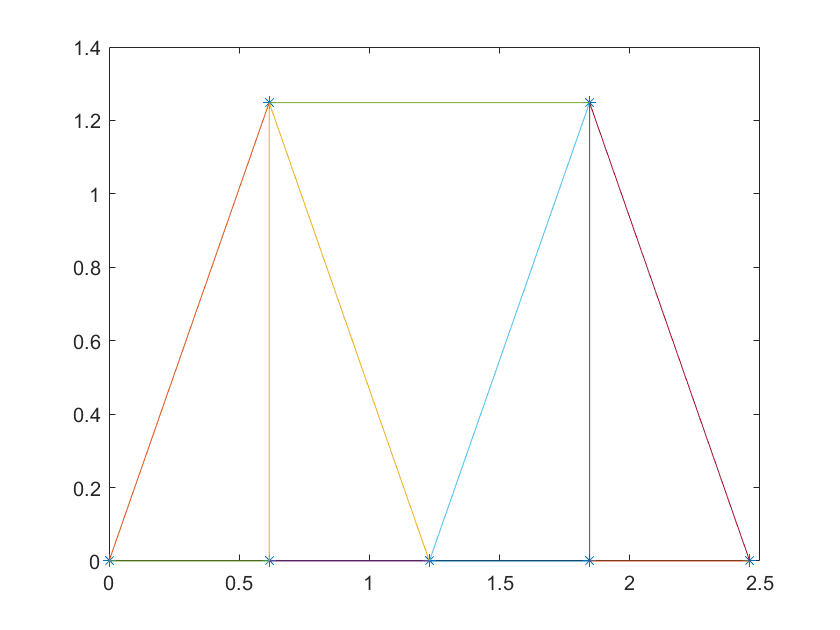


numberElements = 11;
numberNodes = 7;

unit = 0.5*L*cotd(theta);
nodeCoordinates = [
    0 0;    
    unit L;    
    2*unit 0;    
    unit 0;
    3*unit L;    
    4*unit 0;
    
    3*unit 0;
        ];
xx = nodeCoordinates(:,1);
yy = nodeCoordinates(:,2);
plot(xx,yy,"*")

% Connectivity Matrix
elementNodes = [ 
    1 2 ;
    2 3 ;
    4 3;
    1 4;
    3 5 ;
    5 6 ;
    3 7;
    7 6 ;
    4 2;
    7 5;
    2 5;
    ];
plotter(xx,yy,elementNodes,numberElements)


% initialising matrices
GDof = numberNodes;


## Sub Assembly

KsubElement=A*E/3*[7 -8 1;-8 16 -8;1 -8 7]

KsubElement = 	1.0e+08 *

    2.9400   -3.3600    0.4200
   -3.3600    6.7200   -3.3600
    0.4200   -3.3600    2.9400


numberSubElements=4;

subelementnode=[1 2 3;3 4 5;5 6 7;7 8 9];
GDofdash=2*9;%going brute force element is divided into 4 sub elements thus giving us 9 sub nodes in on element

 Ku = zeros(GDofdash);
%     Kt = sym(zeros(GDofc));
%     syms xi
%     N = [xi*(xi-1)/2;(1-xi^2);xi*(1+xi)/2]; % Template for gauss quadrature;
%     Nd = diff(N,xi);
%     NdNd = Nd*Nd';
%     NdN = N*Nd';
K = partb(GDof,numberElements,elementNodes,E,A,xx,yy)

Index exceeds the number of array elements (2).

Error in PartB>partb (line 477)
        elementDof = [2*indice(1)-1, 2*indice(1), 2*indice(2)-1, 2*indice(2), 2*indice(3)-1, 2*indice(3)];

     
%     for e = 1:numberSubElements
%         
%         indice = subelementnode(e,:);
%         elementDof = [2*indice(1)-1, 2*indice(1), 2*indice(2)-1, 2*indice(2), 2*indice(3)-1, 2*indice(3)];
%         xa = xx(indice(3)) - xx(indice(1)); %(delta x)
%         ya = yy(indice(3)) - yy(indice(1));
%         l = sqrt(xa^2 + ya^2); % length of element;
%         
%         c = xa/l;
%         s = ya/l;
%         
%         L1 = [c s 0 0 0 0;0 0 c s 0 0;0 0 0 0 c s];
%         L2 = 0.5*[1 1 0 0 0 0;0 0 1 1 0 0;0 0 0 0 1 1];
%         
%         Kue = sym(zeros(3));
%         Kte = sym(zeros(3));
%         for i = 1:3
%             for j = 1:3
%                 Kue(i,j) = KsubElement(i,j)/l;
% %                 Kte(i,j) = E*A*alpha*Gauss2point(NdN(i,j));
%             end
%         end
% %              Kue=KsubElement/l;
%              
%         Kue = L1'*Kue*L1;
% %         Kte = L2'*Kte*L2;
%         
%         Ku(elementDof,elementDof) = Ku(elementDof,elementDof) + Kue;
% %         Kt(elementDof,elementDof) = Kt(elementDof,elementDof) + Kte;
%         
%     end
% 
% Ku
% temperature = zeros(GDof,1);
% prescribedDof = [1;6]; % Given Temperature at A (node 1)
% prescribedTemp = [TA;298]; %298
% activeDof = setdiff(1:GDof',prescribedDof)';
% 
% stiffness = formStiffnessTemp(GDof,numberElements,numberNodes,elementNodes,K,A,L,xx,yy);
% 
% % Manipulating matrix equation for inversion
% 
% % Removing Prescribed rows
% stiffness(prescribedDof,:) = [];
% 
% % equation required A*t = b
% b = -1*sum(stiffness(:,prescribedDof).*prescribedTemp',2);
% 
% 
% stiffness = stiffness(:,activeDof);
% 
% temperature(prescribedDof) = prescribedTemp;
% temperature(activeDof) = stiffness\b;
% 
% temperature



## Combined Analysis

GDofc = numberNodes*2;
prescribedDof = [1,2,12*2];
activeDof = setdiff(1:GDofc',prescribedDof);
F = zeros(GDofc,1);
P=2e3; 
F([7*2,5*2,14*2]) = [-P,-2*P,-P];
displacements = zeros(GDofc,1);


% Modifying Temperature
T = zeros(size(temperature).*[2,1]);
T(1:2:end) = temperature;
T(2:2:end) = temperature


% [Kt] = formKt(GDofc,numberElements,numberNodes,elementNodes,E,A,L,xx,yy,alpha);
[Ku_actual,Kt] = formStiffnessCombined(GDofc,numberElements,numberNodes,elementNodes,E,A,L,xx,yy,alpha);
% fancy stuff
KtT = Kt*T
F
RHS = F+KtT 

[Ku,RHS1,RHS_Temp] = formKu(GDofc,numberElements,numberNodes,elementNodes,E,A,L,xx,yy,alpha,RHS);

nodesToRemove = [2;4;6;8;9;11;13;15;16;17;18];
DofToRemove = [nodesToRemove*2;nodesToRemove*2-1];

activeDofRound1 = setdiff(activeDof,DofToRemove);

displacements(activeDofRound1) = Ku(activeDofRound1,activeDofRound1)\(RHS1(activeDofRound1));

% Finding the displacements in between
K_ = Ku_actual(:,activeDofRound1);
F_ = displacements(activeDofRound1);
K_ = K_*F_;
Rhs2 = RHS - K_;

displacements = findIntermediateDisplacement(RHS_Temp,T,displacements,GDofc,numberElements,numberNodes,elementNodes,E,A,L,xx,yy,alpha,RHS,nodesToRemove)


xd = displacements(1:2:end);
yd = displacements(2:2:end);

scaling = 100;
X = xx + scaling*xd;
Y = yy + scaling*yd;

plotter(xx,yy,elementNodes,numberElements)
hold on
plotter(X,Y,elementNodes,numberElements)
hold off

## Stress field Analyis

number_of_divisions_per_element = 21;


div = number_of_divisions_per_element;

[temperature_field,stress_field,dudx_field] = calc_Fields(temperature,displacements,numberElements,div,elementNodes,xx,yy,alpha,E);
         div=2/(div-1);
         iterator=[-1:div:1]; 
         stress_field=stress_field
         
        plot(iterator',stress_field/10e10)
        legend("el1","el2","el3","el4","el5","el6","el7","el8","el9","el10","el11")
        plot(iterator',dudx_field)        
        legend("el1","el2","el3","el4","el5","el6","el7","el8","el9","el10","el11")
        plot(iterator,temperature_field)
        legend("el1","el2","el3","el4","el5","el6","el7","el8","el9","el10","el11")
  

## Yield stress matrix

## Functions used

        function stiffness = formStiffnessTemp(GDof,numberElements,numberNodes,elementNodes,K,A,L,xx,yy)

    stiffness = zeros(GDof); % Global Stiffness Matrix initialisation
    syms xi; % The bi-Domain Variable
    temp = [2*xi-1;-4*xi;2*xi+1]; % Template for gauss quadrature;
    temp = temp*temp';

    for e = 1:numberElements
        
        indice = elementNodes(e,:);
        xa = xx(indice(3)) - xx(indice(1)); %(delta x)
        ya = yy(indice(3)) - yy(indice(1));
        l = sqrt(xa^2 + ya^2); % length of element;
        
        Ke = zeros(3);
        for i=1:3
            for j = 1:3;
                Ke(i,j) = K*A/(2*l)*Gauss2point(temp(i,j));
            end
        end
        
        stiffness(indice,indice) = stiffness(indice,indice) + Ke; % Assembly of Global Stiffness
        
    end 
end


function [Ku,Kt] = formStiffnessCombined(GDofc,numberElements,numberNodes,elementNodes,E,A,L,xx,yy,alpha)

    Ku = zeros(GDofc);
    Kt = zeros(GDofc);
    syms xi
    N = [xi*(xi-1)/2;(1-xi^2);xi*(1+xi)/2]; % Template for gauss quadrature;
    Nd = diff(N,xi);
    NdNd = Nd*Nd';
    NdN = N*Nd';
    
     
    for e = 1:numberElements
        
        indice = elementNodes(e,:);
        elementDof = [2*indice(1)-1, 2*indice(1), 2*indice(2)-1, 2*indice(2), 2*indice(3)-1, 2*indice(3)];
        xa = xx(indice(3)) - xx(indice(1)); %(delta x)
        ya = yy(indice(3)) - yy(indice(1));
        l = sqrt(xa^2 + ya^2); % length of element;
        
        c = xa/l;
        s = ya/l;
        
        L1 = [c s 0 0 0 0;0 0 c s 0 0;0 0 0 0 c s];
        L2 = 0.5*[1 1 0 0 0 0;0 0 1 1 0 0;0 0 0 0 1 1];
        
        Kue = zeros(3);
        Kte = zeros(3);
        for i = 1:3
            for j = 1:3
                Kue(i,j) = E*A/(2*l)*Gauss2point(NdNd(i,j));
                Kte(i,j) = E*A*alpha*Gauss2point(NdN(i,j));
            end
        end
             
        Kue = L1'*Kue*L1;
        Kte = L2'*Kte*L2;
        
        Ku(elementDof,elementDof) = Ku(elementDof,elementDof) + Kue;
        Kt(elementDof,elementDof) = Kt(elementDof,elementDof) + Kte;
        
    end
end
function [Ku,Kt] = formStiffnessCombinedNew(GDofc,numberElements,numberNodes,elementNodes,E,A,L,xx,yy,alpha)

    Ku = zeros(GDofc);
    Kt = zeros(GDofc);
%     syms xi
%     N = [xi*(xi-1)/2;(1-xi^2);xi*(1+xi)/2]; % Template for gauss quadrature;
%     Nd = diff(N,xi);
%     NdNd = Nd*Nd';
%     NdN = N*Nd';
    
     
    for e = 1:numberElements
        
        indice = elementNodes(e,:);
        elementDof = [2*indice(1)-1, 2*indice(1), 2*indice(2)-1, 2*indice(2), 2*indice(3)-1, 2*indice(3)];
        xa = xx(indice(3)) - xx(indice(1)); %(delta x)
        ya = yy(indice(3)) - yy(indice(1));
        l = sqrt(xa^2 + ya^2); % length of element;
        
        c = xa/l;
        s = ya/l;
        
        L1 = [c s 0 0 0 0;0 0 c s 0 0;0 0 0 0 c s];
        L2 = 0.5*[1 1 0 0 0 0;0 0 1 1 0 0;0 0 0 0 1 1];
        
        Kue = zeros(3);
        Kte = zeros(3);
        for i = 1:3
            for j = 1:3
                Kue(i,j) = E*A/(2*l)*Gauss2point(NdNd(i,j));
                Kte(i,j) = E*A*alpha*Gauss2point(NdN(i,j));
            end
        end
             
        Kue = L1'*Kue*L1;
        Kte = L2'*Kte*L2;
        
        Ku(elementDof,elementDof) = Ku(elementDof,elementDof) + Kue;
        Kt(elementDof,elementDof) = Kt(elementDof,elementDof) + Kte;
        
    end
end

function [Kt] = formKt(GDofc,numberElements,numberNodes,elementNodes,E,A,L,xx,yy,alpha)


    Kt = zeros(GDofc);
    syms xi
    N = [xi*(xi-1)/2;(1-xi^2);xi*(1+xi)/2]; % Template for gauss quadrature;
    Nd = diff(N,xi);
    NdNd = Nd*Nd';
    NdN = N*Nd';
     
    for e = 1:numberElements
        
        indice = elementNodes(e,:);
        elementDof = [2*indice(1)-1, 2*indice(1), 2*indice(2)-1, 2*indice(2), 2*indice(3)-1, 2*indice(3)];
        xa = xx(indice(3)) - xx(indice(1)); %(delta x)
        ya = yy(indice(3)) - yy(indice(1));
        l = sqrt(xa^2 + ya^2); % length of element;
        
        c = xa/l;
        s = ya/l;
        
        L1 = [c s 0 0 0 0;0 0 c s 0 0;0 0 0 0 c s];
        L2 = 0.5*[1 1 0 0 0 0;0 0 1 1 0 0;0 0 0 0 1 1];

        Kte = zeros(3);
        for i = 1:3
            for j = 1:3
                Kte(i,j) = -1*2*E*A*alpha/l*Gauss2point(NdN(i,j));
            end
        end
        
        
        
%         Kte = Kte + E*A*alpha*[-1 0 0;0 0 0;0 0 1];
       

        Kte = L2'*Kte*L2;
        

        Kt(elementDof,elementDof) = Kt(elementDof,elementDof) + Kte;
        
    end
end

function [Ku,RHS1,RHS_Temp] = formKu(GDofc,numberElements,numberNodes,elementNodes,E,A,L,xx,yy,alpha,RHS)

    Ku = zeros(GDofc);
    RHS_Temp = zeros(size(RHS));
    RHS1 = RHS;
    
    syms xi
    N = [xi*(xi-1)/2;(1-xi^2);xi*(1+xi)/2]; % Template for gauss quadrature;
    Nd = diff(N,xi);
    NdNd = Nd*Nd';
    NdN = N*Nd';
    
     
    for e = 1:numberElements
        
        indice = elementNodes(e,:);
        elementDof = [2*indice(1)-1, 2*indice(1), 2*indice(2)-1, 2*indice(2), 2*indice(3)-1, 2*indice(3)];
        xa = xx(indice(3)) - xx(indice(1)); %(delta x)
        ya = yy(indice(3)) - yy(indice(1));
        l = sqrt(xa^2 + ya^2); % length of element;
        
        c = xa/l;
        s = ya/l;
        
        L1 = [c s 0 0 0 0;0 0 c s 0 0;0 0 0 0 c s];
        L2 = 0.5*[1 1 0 0 0 0;0 0 1 1 0 0;0 0 0 0 1 1];
        
        Kue = zeros(3);
        for i = 1:3
            for j = 1:3
                Kue(i,j) = E*A/(2*l)*Gauss2point(NdNd(i,j));
            end
        end
        
        Kue(:,1) = Kue(:,1) + 0.5*Kue(:,2);
        Kue(:,3) = Kue(:,3) + 0.5*Kue(:,2);
        Kue(2,:) = 0;
        Kue(:,2) = 0;
       
        Kue = L1'*Kue*L1;
        
        middleDof = elementDof(3:4);
        RHS_Temp(middleDof) = RHS(middleDof);
        RHS1(middleDof) = 0;
        
        Ku(elementDof,elementDof) = Ku(elementDof,elementDof) + Kue;
        
    end
end

function displacement1 = findIntermediateDisplacement(RHS_Temp,T,displacement,GDofc,numberElements,numberNodes,elementNodes,E,A,L,xx,yy,alpha,RHS,nodesToRemove)
    displacement1 = displacement;
    for e = 1:numberElements
        indice = elementNodes(e,:);
        elementDof = [2*indice(1)-1, 2*indice(1), 2*indice(2)-1, 2*indice(2), 2*indice(3)-1, 2*indice(3)];
         xa = xx(indice(3)) - xx(indice(1)); %(delta x)
        ya = yy(indice(3)) - yy(indice(1));
        l = sqrt(xa^2 + ya^2); % length of element;
         c = xa/l;
        s = ya/l;
        displacement1(2*indice(2)-1)= -1*c*3*l*alpha*2/3*(T(2*indice(1))+T(2*indice(2)))+3/8*4/3*(displacement1(2*indice(1)-1)+displacement1(2*indice(3)-1));
        displacement1(2*indice(2))= -1*s*3*l*alpha*2/3*(T(2*indice(1))+T(2*indice(2)))+3/8*4/3*(displacement1(2*indice(1))+displacement1(2*indice(3)));
        
        
    end

end


function [temperature_field,stress_field,dudx_field] = calc_Fields(temperature,displacements,numberElements,div,elementNodes,xx,yy,alpha,E)

    temperature_field = zeros(div,numberElements);
    dudx_field = zeros(div,numberElements);
    div=2/(div-1);
         iterator=[-1:div:1];
        [m,n]=size(iterator);
        stress_field=zeros(n,numberElements);    
    
    for e = 1:numberElements
        indice = elementNodes(e,:);
        elementDof = [2*indice(1)-1, 2*indice(1), 2*indice(2)-1, 2*indice(2), 2*indice(3)-1, 2*indice(3)];
        xa = xx(indice(3)) - xx(indice(1)); %(delta x)
        ya = yy(indice(3)) - yy(indice(1));
        l = sqrt(xa^2 + ya^2); % length of element;
         c = xa/l;
        s = ya/l;  
        syms xi;
        shape_function1=xi*(xi-1)/2;
        shape_function2=(1-xi^2);
        shape_function3=xi*(1+xi)/2;
              
        T = temperature(indice(1))*shape_function1+temperature(indice(2))*shape_function2+temperature(indice(3))*shape_function3;
        U_x=displacements(2*indice(1)-1)*shape_function1+displacements(2*indice(2)-1)*shape_function2+displacements(2*indice(3)-1)*shape_function3;
        U_y=displacements(2*indice(1))*shape_function1+displacements(2*indice(2))*shape_function2+displacements(2*indice(3))*shape_function3;
        U=(displacements(2*indice(1)-1)*c+displacements(2*indice(1))*s)*shape_function1+(displacements(2*indice(2)-1)*c+displacements(2*indice(2))*s)*shape_function2+(displacements(2*indice(3)-1)*c+displacements(2*indice(3))*s)*shape_function3;
        strain=diff(U);
        stress_field_function=E*(strain-alpha*(T-298));
            
         for i=1:n
            dudx_field(i,e)=subs(strain,iterator(1,i));
        end
        for i=1:n
            temperature_field(i,e)=subs(T,iterator(1,i));
        end
        for i=1:n
            stress_field(i,e)=subs(stress_field_function,iterator(1,i));
        end     
        
    end
    

end


function K = partb(GDof,numberElements,elementNodes,E,A,xx,yy)
    
    K = zeros(GDof);
    
    for e = 1:numberElements
        
        indice = elementNodes(e,:);
        elementDof = [2*indice(1)-1, 2*indice(1), 2*indice(2)-1, 2*indice(2), 2*indice(3)-1, 2*indice(3)];
        xa = xx(indice(3)) - xx(indice(1)); %(delta x)
        ya = yy(indice(3)) - yy(indice(1));
        l = sqrt(xa^2 + ya^2); % length of element;
        
        c = xa/l;
        s = ya/l;
        
        L1 = [c s 0 0 0 0;0 0 c s 0 0;0 0 0 0 c s];
        
        % Find Ke
        number_subelements = 4;
        lsub = l/4;
        Kele = E*A/(3*lsub)*[7 -8 1; -8 16 -8;1 -8 7];
        subElementNodes = [1 2 3;3 4 5;5 6 7;7 8 9];
        Ke = zeros(9);
        for i = 1:4
            indice = subElementNodes(i,:);
%             subElementDof = [2*indice(1)-1;2*indice(1);2*indice(2)-1;2*indice(2);2*indice(3)-1;2*indice(3)];
            subElementDof = indice;
            Ke(subElementDof,subElementDof) = Ke(subElementDof,subElementDof) + Kele;
        end

        % Ke is bada element matrix ......
        % Find 2*2 matrix at last line........
        
        K(elementDof,elementDof) = K(elementDof,elementDof) + Ke;
          
    end

end
function A = Gauss2point(exp)
    temp = 1/sqrt(3); % Gauss Quadrature Point
    A = subs(exp,temp) + subs(exp,-1*temp);
end

function plotter(xx,yy,elementNodes,numberElements)
    hold on
    for i = 1:numberElements
        Nodes = elementNodes(i,:);
        Nodei = Nodes(1);
        Nodej = Nodes(2);
        
        x = [xx(Nodei) xx(Nodej)];
        y = [yy(Nodei) yy(Nodej)];
        
        plot(x,y)
        
%         Nodei = Nodes(2);
%         Nodej = Nodes(3);
%         
%         x = [xx(Nodei) xx(Nodej)];
%         y = [yy(Nodei) yy(Nodej)];

%         Nodei = Nodes(1);
%         Nodej = Nodes(3);
%         
%         x = [xx(Nodei) xx(Nodej)];
%         y = [yy(Nodei) yy(Nodej)];
        
%         plot(x,y)
    end
    hold off
end
